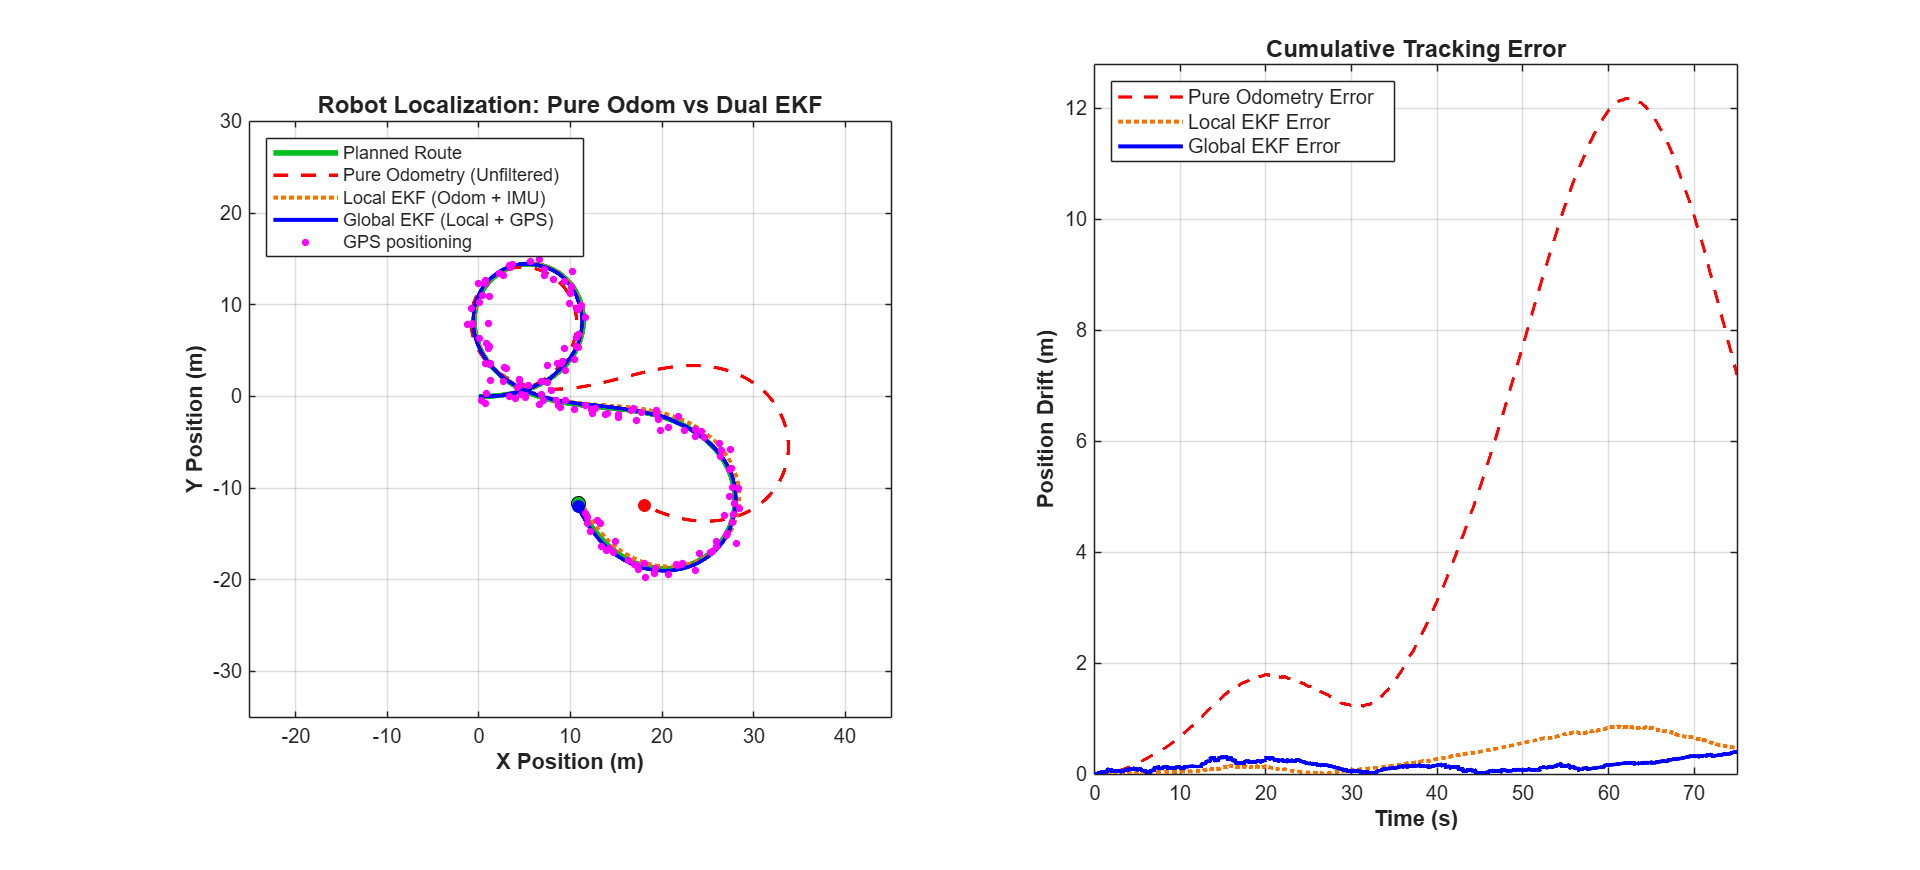

%% Dual-EKF Localization Demonstration (Fast & Smooth 60 FPS Playback)
clear; clc; close all;
rng(102); % Reproducible noise

%% 1. Simulation & Video Timing Setup
target_fps = 60;              % Target video frame rate
dt = 1 / target_fps;          % Base physics step (~0.01667 s)
T_total = 75;                 % Total simulation duration (s)
time = 0:dt:T_total;
N = length(time);

% Playback / Rendering Speed Control:
% 1 = 1x real-time (slower)
% 3 = 3x faster playback
% 4 = 4x faster playback
playback_speedup = 3; 

% GPS update interval (e.g., 2 Hz updates -> every 30 base steps)
gps_update_interval = round(target_fps / 2); 

% Video Export Controls
record_video = false;         % Set to TRUE to export MP4
video_filename = 'dual_ekf_fast_60fps.mp4';

%% 2. Ground Truth Trajectory (Smooth Multi-Turn Course)
v_true = 1.3 * ones(1, N);                                      % Forward velocity (m/s)
w_true = 0.18 * sin(0.08 * time) + 0.05 * cos(0.025 * time);   % Steering rate (rad/s)

x_true = zeros(3, N); % [x; y; theta]
for k = 1:N-1
    th = x_true(3, k);
    x_true(1, k+1) = x_true(1, k) + v_true(k) * cos(th) * dt;
    x_true(2, k+1) = x_true(2, k) + v_true(k) * sin(th) * dt;
    x_true(3, k+1) = wrapToPi(th + w_true(k) * dt);
end

%% 3. Sensor Noise Parameters
% A. Wheel Encoders (High slip & angular bias)
sigma_v_odom = 0.12;
sigma_w_odom = deg2rad(2.5);
bias_w_odom  = deg2rad(0.50); % Constant odometry bias driving progressive drift

% B. IMU Gyro (Low short-term noise, minor bias)
sigma_w_imu  = deg2rad(0.35);
bias_w_imu   = deg2rad(0.03);

% C. GPS Sensor (Absolute position, noisy, zero long-term drift)
sigma_gps    = 0.6;           % Horizontal accuracy (m)

%% 4. State & Covariance Initializations
x_pure_odom = zeros(3, N);
x_local_ekf = zeros(3, N);
x_glob_ekf  = zeros(3, N);

P_local = diag([0.1^2, 0.1^2, deg2rad(1)^2]);
P_glob  = diag([0.1^2, 0.1^2, deg2rad(1)^2]);

Q_local = diag([sigma_v_odom^2, sigma_w_imu^2]);
R_gps   = diag([sigma_gps^2, sigma_gps^2]);

%% 5. Simulation Execution
gps_meas_history = nan(2, N);

for k = 1:N-1
    % --- Raw Sensor Readings ---
    v_raw_odom = v_true(k) + sigma_v_odom * randn();
    w_raw_odom = w_true(k) + bias_w_odom + sigma_w_odom * randn();
    w_raw_imu  = w_true(k) + bias_w_imu  + sigma_w_imu  * randn();

    % 1. Pure Odometry (Dead Reckoning)
    th_po = x_pure_odom(3, k);
    x_pure_odom(1, k+1) = x_pure_odom(1, k) + v_raw_odom * cos(th_po) * dt;
    x_pure_odom(2, k+1) = x_pure_odom(2, k) + v_raw_odom * sin(th_po) * dt;
    x_pure_odom(3, k+1) = wrapToPi(th_po + w_raw_odom * dt);

    % 2. Local EKF: Fuse Wheel Speed (v) + IMU Gyro (w)
    th_loc = x_local_ekf(3, k);
    x_loc_pred = [x_local_ekf(1, k) + v_raw_odom * cos(th_loc) * dt;
                  x_local_ekf(2, k) + v_raw_odom * sin(th_loc) * dt;
                  wrapToPi(th_loc + w_raw_imu * dt)];

    Fx_loc = [1, 0, -v_raw_odom * sin(th_loc) * dt;
              0, 1,  v_raw_odom * cos(th_loc) * dt;
              0, 0,  1];
    Fw_loc = [cos(th_loc)*dt, 0; sin(th_loc)*dt, 0; 0, dt];
    P_local = Fx_loc * P_local * Fx_loc' + Fw_loc * Q_local * Fw_loc';
    x_local_ekf(:, k+1) = x_loc_pred;

    % 3. Global EKF: Fused Odometry + Periodic GPS Fixes
    th_gl = x_glob_ekf(3, k);
    x_gl_pred = [x_glob_ekf(1, k) + v_raw_odom * cos(th_gl) * dt;
                 x_glob_ekf(2, k) + v_raw_odom * sin(th_gl) * dt;
                 wrapToPi(th_gl + w_raw_imu * dt)];

    Fx_gl = [1, 0, -v_raw_odom * sin(th_gl) * dt;
             0, 1,  v_raw_odom * cos(th_gl) * dt;
             0, 0,  1];
    Fw_gl = [cos(th_gl)*dt, 0; sin(th_gl)*dt, 0; 0, dt];
    P_glob = Fx_gl * P_glob * Fx_gl' + Fw_gl * Q_local * Fw_gl';

    % GPS Measurement Update
    if mod(k, gps_update_interval) == 0
        z_gps = [x_true(1, k+1) + sigma_gps * randn();
                 x_true(2, k+1) + sigma_gps * randn()];
        gps_meas_history(:, k+1) = z_gps;

        H_gps = [1, 0, 0;
                 0, 1, 0];
        y_gps = z_gps - H_gps * x_gl_pred;
        S_gps = H_gps * P_glob * H_gps' + R_gps;
        K_gps = (P_glob * H_gps') / S_gps;

        x_gl_pred = x_gl_pred + K_gps * y_gps;
        x_gl_pred(3) = wrapToPi(x_gl_pred(3));
        P_glob = (eye(3) - K_gps * H_gps) * P_glob;
    end
    x_glob_ekf(:, k+1) = x_gl_pred;
end

% Compute position errors
err_odom = hypot(x_pure_odom(1, :) - x_true(1, :), x_pure_odom(2, :) - x_true(2, :));
err_loc  = hypot(x_local_ekf(1, :) - x_true(1, :), x_local_ekf(2, :) - x_true(2, :));
err_glob = hypot(x_glob_ekf(1, :)  - x_true(1, :), x_glob_ekf(2, :)  - x_true(2, :));

%% 6. Video Writer Setup
if record_video
    v_out = VideoWriter(video_filename, 'MPEG-4');
    v_out.FrameRate = target_fps; % Pure 60 FPS output
    v_out.Quality = 100;
    open(v_out);
    fprintf('Recording accelerated 60 FPS video to %s ...\n', video_filename);
end

%% 7. Presentation Figure Setup
fig = figure('Color', [1 1 1], 'Position', [50, 60, 1280, 580]);

% Left Subplot: Spatial 2D Map
subplot(1, 2, 1);
hold on; grid on; axis equal; box on;
xlim([-25, 45]); ylim([-35, 30]);
xlabel('X Position (m)', 'FontWeight', 'bold');
ylabel('Y Position (m)', 'FontWeight', 'bold');
title('Robot Localization: Pure Odom vs Dual EKF', 'FontSize', 12);

% Ground Truth (Vivid Green)
h_true = plot(x_true(1, :), x_true(2, :), '-', 'Color', [0.0, 0.75, 0.12], ...
              'LineWidth', 2.8, 'DisplayName', 'Planned Route');

% Trajectory Lines
h_odom = plot(nan, nan, 'r--', 'LineWidth', 1.8, 'DisplayName', 'Pure Odometry (Unfiltered)');
h_loc  = plot(nan, nan, ':',   'Color', [0.95, 0.45, 0.0], 'LineWidth', 2.0, 'DisplayName', 'Local EKF (Odom + IMU)');
h_glob = plot(nan, nan, 'b-',  'LineWidth', 2.0, 'DisplayName', 'Global EKF (Local + GPS)');
h_gps_pt = plot(nan, nan, 'm.', 'MarkerSize', 11, 'DisplayName', 'GPS positioning');

% Current Position Markers
h_true_pos = plot(nan, nan, 'o', 'MarkerFaceColor', [0.0, 0.75, 0.12], 'MarkerEdgeColor', 'k', 'MarkerSize', 7);
h_odom_pos = plot(nan, nan, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);
h_glob_pos = plot(nan, nan, 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 6);

legend([h_true, h_odom, h_loc, h_glob, h_gps_pt], 'Location', 'northwest', 'FontSize', 9);

% Right Subplot: Real-Time Error Plot
subplot(1, 2, 2);
hold on; grid on; box on;
xlim([0, T_total]); ylim([0, max(err_odom) * 1.05]);
xlabel('Time (s)', 'FontWeight', 'bold');
ylabel('Position Drift (m)', 'FontWeight', 'bold');
title('Cumulative Tracking Error', 'FontSize', 12);

h_err_odom = plot(nan, nan, 'r--', 'LineWidth', 1.6, 'DisplayName', 'Pure Odometry Error');
h_err_loc  = plot(nan, nan, ':',   'Color', [0.95, 0.45, 0.0], 'LineWidth', 2.0, 'DisplayName', 'Local EKF Error');
h_err_glob = plot(nan, nan, 'b-',  'LineWidth', 2.0, 'DisplayName', 'Global EKF Error');
legend('Location', 'northwest', 'FontSize', 10);

%% 8. Fast & Fluid Render Loop
for k = 1:playback_speedup:N
    % Update trajectories
    set(h_odom, 'XData', x_pure_odom(1, 1:k), 'YData', x_pure_odom(2, 1:k));
    set(h_loc,  'XData', x_local_ekf(1, 1:k), 'YData', x_local_ekf(2, 1:k));
    set(h_glob, 'XData', x_glob_ekf(1, 1:k),  'YData', x_glob_ekf(2, 1:k));
    
    % Update GPS fixes
    valid_gps = ~isnan(gps_meas_history(1, 1:k));
    set(h_gps_pt, 'XData', gps_meas_history(1, valid_gps), ...
                  'YData', gps_meas_history(2, valid_gps));
    
    % Update vehicle heads
    set(h_true_pos, 'XData', x_true(1, k),      'YData', x_true(2, k));
    set(h_odom_pos, 'XData', x_pure_odom(1, k), 'YData', x_pure_odom(2, k));
    set(h_glob_pos, 'XData', x_glob_ekf(1, k),  'YData', x_glob_ekf(2, k));
    
    % Update error curves
    set(h_err_odom, 'XData', time(1:k), 'YData', err_odom(1:k));
    set(h_err_loc,  'XData', time(1:k), 'YData', err_loc(1:k));
    set(h_err_glob, 'XData', time(1:k), 'YData', err_glob(1:k));
    
    drawnow limitrate; % High-performance rendering
    
    if record_video
        writeVideo(v_out, getframe(fig));
    end
end


if record_video
    close(v_out);
    fprintf('Video saved successfully as %s!\n', video_filename);
end